# Discrete Cosine Transformation

P Aditya Krishna Rohit

CB.EN.P2CEN20002

**Basic terminology **

What is a signal?

$\to$A signal is a function that conveys information about a phenomenon. It may also refers to any time varying voltage, current or electromagnetic wave that carries information.

$\to$So here, we talk about cosine signals extracted from an image 

Orthogonal bases?

$\to$Orthogonality means being perpendicual to something.

**What is DCT**

$\to$DCT is an orthogonal transformation method decomposes an image(mostly) to its spatial frequency spectrum. 

$\to$DCT represents an image as a sum of sinusoids of varying magnitudes and frequencies.

$\to$It expresses a finite sequence of data points in terms of sum of cosine funtions oscillating at different frequencies.

$\to$Mainly the DCT is used for compressing tasks, like image compression where for example high frequency components can be discarded. 

$\to$DCT is a type DFT(Discrete fourier transform). But DFT uses complex numbers and DCT uses only real numbers.

$\to$The main objective od DCT is to transform $N\;\textrm{real}\;\textrm{numbers}\;x_0 ,x_1 ,\ldotp \ldotp \ldotp \ldotp ,x_{N-1}$ to $N\;\textrm{real}\;\textrm{numbers}$$X_0 ,\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp ,X_{n-1}$.

$\to$Now let us try to create a sample DCT matrix taking some random vector with length of the signal as 4.

clc;clear;
N = 4;
b = (0:N-1)*pi/N + pi/(2*N); % row vector
mul = (0:N-1)'; % column vector
D = cos(mul*b); % row wise bases (D*D'=diagonal)
div = [sqrt(N),ones(1,N-1)*sqrt(N/2)]'; 
DCTmatrix = D./repmat(div,1,N) % rowwise normalized bases 

DCTmatrix =     0.5000    0.5000    0.5000    0.5000
    0.6533    0.2706   -0.2706   -0.6533
    0.5000   -0.5000   -0.5000    0.5000
    0.2706   -0.6533    0.6533   -0.2706


T=DCTmatrix;

Or we can directly create the matrix using the in-built function dct(eye(N)) or dctmtx(N). And we can verify that all these methods will give same results.

DCT1 = dct(eye(N));
DCT2 = dctmtx(N);

Now these bases created are orthogonal bases. That means they are orthogonal to each other. Lets check that

DCT1(1,:)*DCT1(2,:)'

ans = 0

DCT1(2,:)*DCT1(3,:)'

ans = 0

DCT1(1,:)*DCT1(4,:)'

ans = 0

Now we'll see the variants of DCT - 

Formally, the discrete cosine transformation is a linear, invertible funtion $f:R^N \to R^N$, (R denotes set of real numbers). So the DCT matrix is an invertible matrix. We have  types of DCT variants. But I discuss only type $\textrm{II}\;$ variant.

**DCT-II**

This is the 1st variant proposed by Nasir Ahmed. And this is the most commonly used form. The transformation formula :


$$\Sigma_{n=0}^{N-1$$

$$x_n \;\cos \left(\frac{\Pi }{N}\left(n+\frac{1}{2}\right)k\right)\;\;k=0,\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp ,N-1$$


**2D - DCT** :

DCT of the input signal is calculated when we have the basis function $f\left(x,y\right),$ we have to calculate $F\left(p,q\right)$.

The two-dimentional DCT of an $M$x $N\;$image $f\left(x,y\right)$ is defined as follows:

            
$$F\left(p,q\right)=\alpha_{p\;} \alpha_q \;\Sigma_{x=0}^{M-1} \;\ldotp \Sigma_{y=0}^{N-1} \;f\left(x,y\right)\ldotp \cos \left\lbrack \pi \left(2x+1\right)\frac{p}{2M}\right\rbrack \ldotp \cos \left\lbrack \pi \left(2y+1\right)\frac{q}{2N}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\to \left(1\right)$$


where,  $0\le p\le M-1\;\;\;\;\;\&\;\;\;\;\;\;0\le q\le N-1$

$\begin{array}{l}
\textrm{and}\\
\;\alpha_p =\left\lbrace \frac{1}{\sqrt{M}}\;,p=0\;\;\;\;\;\;\;\;\;\;\;\;\&\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\sqrt{\frac{2}{M}}\;,1\le p\le M-1\right\rbrace 
\end{array}$,


$$\alpha_q =\left\lbrace \frac{1}{\sqrt{N}}\;,q=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\&\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\sqrt{\frac{2}{N}}\;,1\le q\le N-1\right\rbrace$$


**Inverse DCT** :

Inverse DCT is the calculation of the inverse DCT of the input signal i.e matrix

So here we find $f\left(x,y\right)$ when we have $F\left(p,q\right)$.

So the equation is, 

        
$$f\left(x,y\right)=\Sigma_{p=0}^{M-1} \ldotp \Sigma_{q=0}^{N-1} \;\alpha_p \alpha_q F\left(p,q\right)\ldotp \cos \left\lbrack \pi \left(2x+1\right)\frac{p}{2M}\right\rbrack \ldotp \cos \left\lbrack \pi \left(2y+1\right)\frac{q}{2N}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\to \left(2\right)$$


where, $\begin{array}{l}
0\le x\le M-1\\
0\le y\le N-1
\end{array}$,

and


$$\alpha_p =\left\lbrace \frac{1}{\sqrt{M}}\;,p=0\;\;\;\;\;\;\;\;\;\;\;\;\&\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\sqrt{\frac{2}{M}}\;,1\le p\le M-1\right\rbrace$$



$$\alpha_q =\left\lbrace \frac{1}{\sqrt{N}}\;,q=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\&\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\sqrt{\frac{2}{N}}\;,1\le q\le N-1\right\rbrace$$


So, in both the equations we have somethingin common.

$\alpha_{p\;\;} \;\;\;\&\;\;\;\;\;\alpha_q$ are the coefficient matrix  and

$\alpha_p \alpha_q$$\cos \left\lbrack \pi \left(2x+1\right)\frac{p}{2M}\right\rbrack \ldotp \cos \left\lbrack \pi \left(2y+1\right)\frac{q}{2N}\right\rbrack$is thebasis functions of DCT

# Now I'll do image compression using DCT

Now I try to generate the basis functions.

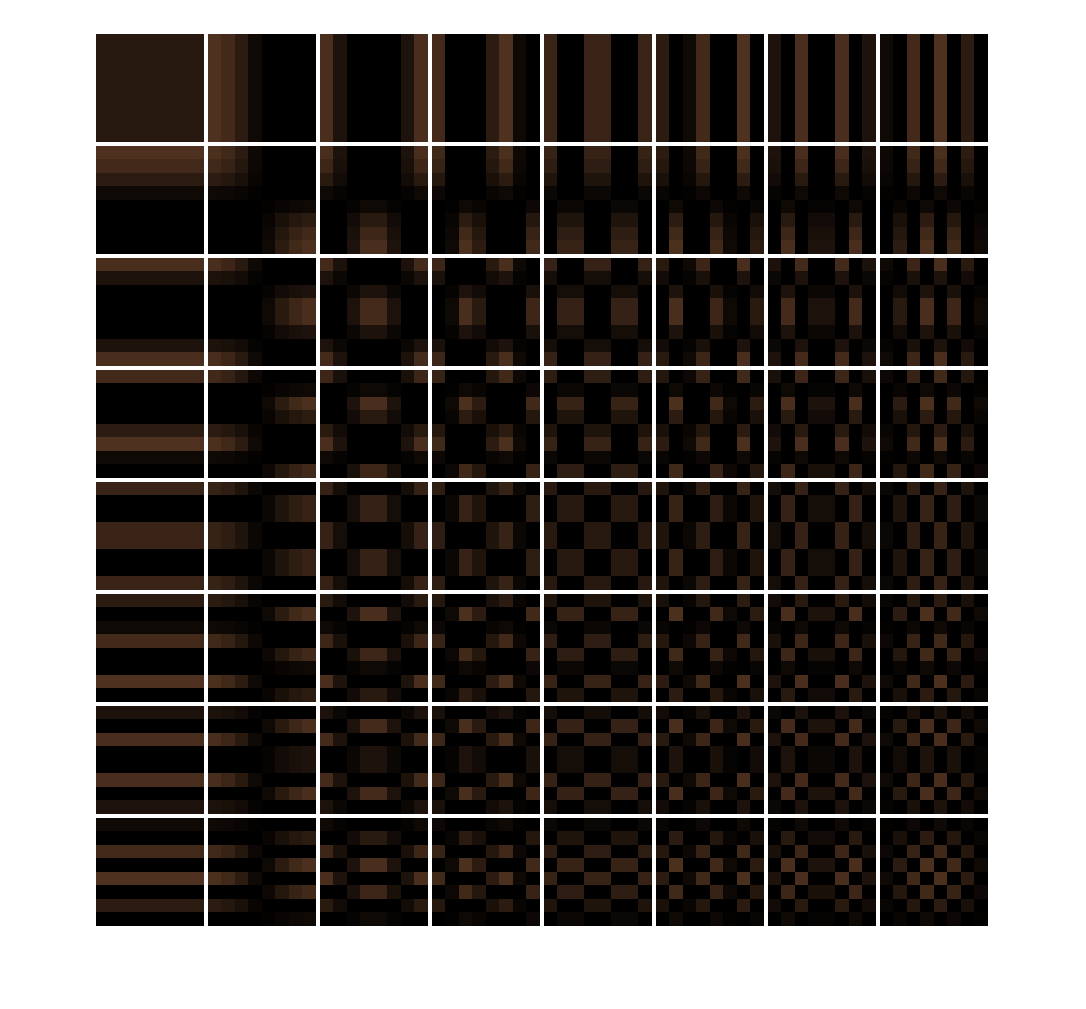

M = 8; N = 8; % 8x8 matrix
B = zeros([8 8]);
for P = 1:M
    p = P-1;
    for Q = 1:N
        q = Q-1;
        if p == 0 && q == 0
            ap = 1/(sqrt(M)); % ap is alphap and aq is alphaq
            aq = 1/(sqrt(N));
        else
            ap = sqrt(2/M);
            aq = sqrt(2/N);
        end
        for x = 1:M
            for y = 1:N
                B(x,y) = ap*aq*cos((pi*p*(2*(x-1)+1))/(2*M))*cos((pi*q*(2*(y-1)+1))/(2*N));
            end
        end
        basisimg = ind2rgb(im2uint8(B),copper);
        filename = strcat(num2str(p),num2str(q),'.png');
        imwrite(imresize(basisimg,[64 64],'nearest'),filename);
    end
end
imds = imageDatastore(fullfile("D:\OneDrive - Amrita Vishwa Vidyapeetham\Linear Algebra\Project","*.png"));
montage(imds,'BackgroundColor','white','BorderSize',[2,2]);

So we can see here, the horizontal frequencies increase from left to the right , and the vertical frequencies increase from top to bottom.

But if we have to compute DCT for any image, we cannod do that using the basis functions. Because, this approach is fixed to 'one' image segment (in this example we took 8x8).

So to compute DCT of the image, we go for another approach called Transformation matrix

**Transformation Matrix**

This method can also suitable for small image segments such as 8x8, 16x16 etc.

For this, a DCT Transformation matrix T is computed first for MxM segment by the following equation:


$$\begin{array}{l}
T=\left\lbrace \frac{1}{\sqrt{M}}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;p=0,\;\;\;\;0\le q\le M-1\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\left\lbrace \sqrt{\frac{2}{M}\;\cos \left\lbrack \pi \left(2q+1\right)\frac{p}{2M}\right\rbrack }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;1\le p\le M-1\;,0\le q\le M-1\;\right\rbrace 
\end{array}$$


After finding the DCT transformation matrix T, then DCT of an image segment $f\left(x,y\right)$ can be found by

        
$$F\left(p,q\right)=T*f\left(x,y\right)*T^{\prime }$$


We can do this is matlab using an inbuilf function dctmtx()

So lets try to implement this

img = imread('cameraman.tif');
img = double(img);
T = dctmtx(8);
dct = @(block_struct) T * block_struct.data * T'; % Block processing
C = blockproc(img, [8 8], dct); % Finding DCT using block processing

Now I'll have take only low frequency coefficients of the block and leaving high frequency coeffs. So I'm taking a mask vector.

mask = [1 1 1 1 0 0 0 0
        1 1 1 0 0 0 0 0 
        1 1 0 0 0 0 0 0 
        1 0 0 0 0 0 0 0 
        0 0 0 0 0 0 0 0 
        0 0 0 0 0 0 0 0
        0 0 0 0 0 0 0 0
        0 0 0 0 0 0 0 0];

Now truncate the DCT coefficients

ct = blockproc(C, [8 8], @(block_struct) (mask.*block_struct.data));
invdct = @(block_struct) T' * (block_struct.data)*T;
invC = blockproc(ct, [8 8], invdct); % Finding inverse DCT

Now, I'll compare both the images

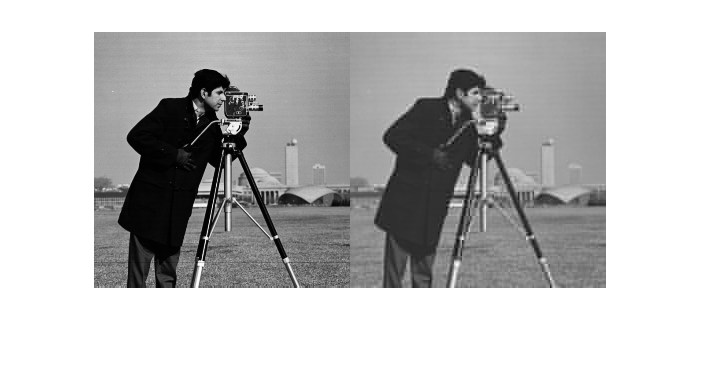

figure
imshowpair(img, invC,'montage')

We can see clearly that quality of the image is reduced

We have another approach which can be done by dct2() in matlab.

Using this function, we can compute the DCT of that image as a full, not by blocks.

This method is very efficient for more bigger images

Now let us try with this function

img1 = imread('Photo.jpg');
I = im2gray(img1);

C = dct2(I);
C(1:8,1:8)

ans = 	1.0e+05 *

    2.0108   -0.2083   -0.0533    0.0805    0.1652    0.0452    0.1591    0.0147
    0.2109    0.0543   -0.0985   -0.1213    0.0072    0.0595    0.0272   -0.0406
    0.2004   -0.0238   -0.0225   -0.0172   -0.0166   -0.0218    0.0005    0.0157
   -0.1921    0.1425    0.0473    0.0665   -0.0117   -0.1119    0.0200   -0.0404
    0.0134    0.1086    0.0288   -0.0142   -0.0101   -0.0090   -0.0533   -0.0482
    0.0459   -0.0743    0.0441    0.0464   -0.0246    0.0240   -0.0447    0.0293
    0.1232    0.0589    0.0198   -0.0127   -0.0175    0.0166   -0.0137   -0.0047
    0.0675   -0.1126   -0.0420    0.0163    0.0200    0.0285   -0.0115    0.0501


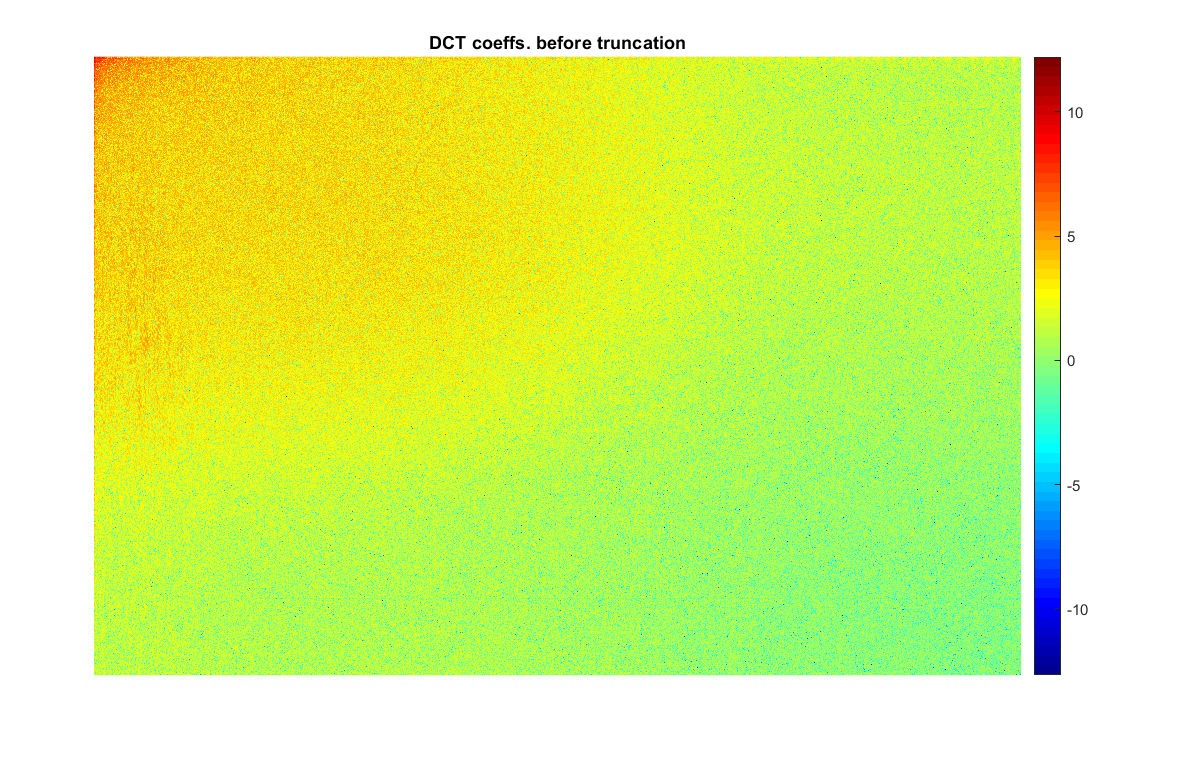

 figure
 imshow(log(abs(C)),[])
 title('DCT coeffs. before truncation');
 colormap(gca,jet(64))
 colorbar 

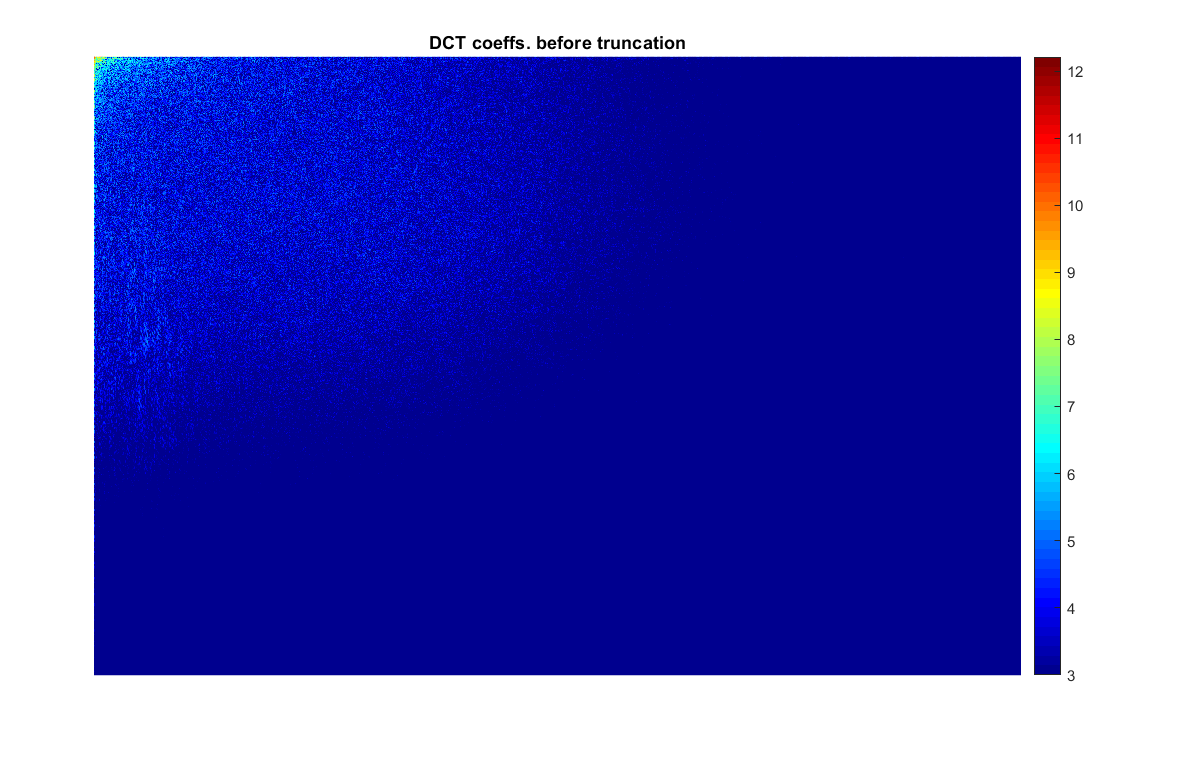

C(abs(C) < 20) = 0;

figure
imshow(log(abs(C)),[])
title('DCT coeffs. before truncation');
colormap(gca,jet(64))
colorbar


Ct = idct2(C);
Ct(1:8,1:8)

ans =   250.5700  244.7239  254.6362  265.7527  251.5892  238.0262  253.4820  264.6599
  256.9654  254.4780  255.3651  259.5895  258.7130  254.9929  260.1787  263.9643
  250.9547  257.2707  255.6442  252.8617  258.3745  258.7451  254.4207  256.1177
  246.7426  256.6374  257.6520  251.3721  252.7392  253.1683  250.8034  255.8158
  254.3772  257.6624  258.6832  253.2961  251.7431  254.0317  256.1812  259.4459
  258.8119  257.2706  258.4230  255.7279  254.5894  255.2843  252.9509  252.5803
  257.7060  258.2277  259.5679  255.8958  255.4098  254.5588  248.3399  250.6837
  258.2478  261.4538  261.6171  255.0649  255.0170  256.8430  253.8411  258.6628


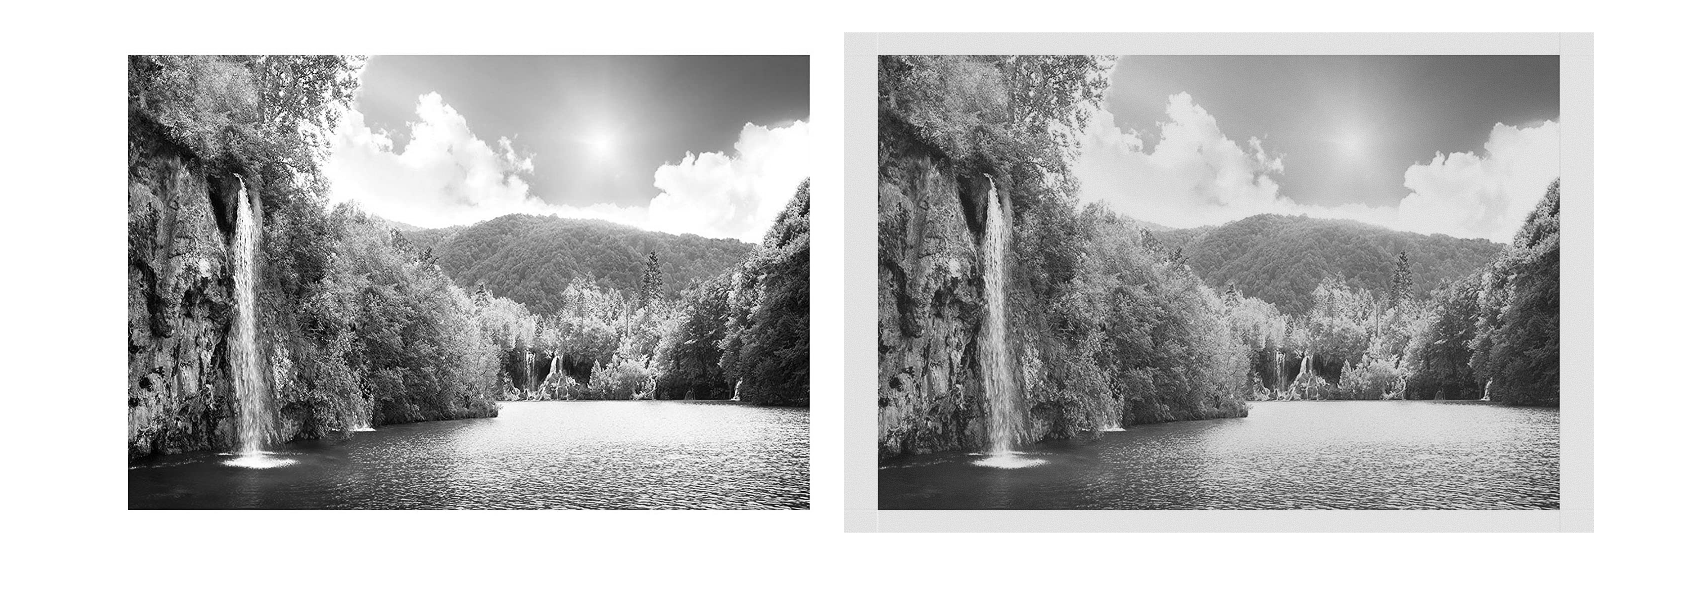

figure
imshowpair(I,Ct,'montage')